# `Modeling Parachute Motion with Matlab `  

Now that we got some practice with using Matlab to model dynamical systems, let's try a slightly more challenging problem of a falling parachute.

Recall that:

- Air resistance/drag/friction played a major role in determining the dynamics in the falling parachute example.    

- We focused only on the dynamics in y-direction. 

- We modeled the friction forces as $F_f =\alpha \;V^2$where $\alpha \;=\frac{1}{2}\rho_{\textrm{air}} \;AC_D \;$is determined by the shape of the parachute ($A$ and $C_D$) and air density $\rho_{\textrm{air}} \;$.

-  We used the "Dynamic Model" feature of Tracker to solve the equations. 

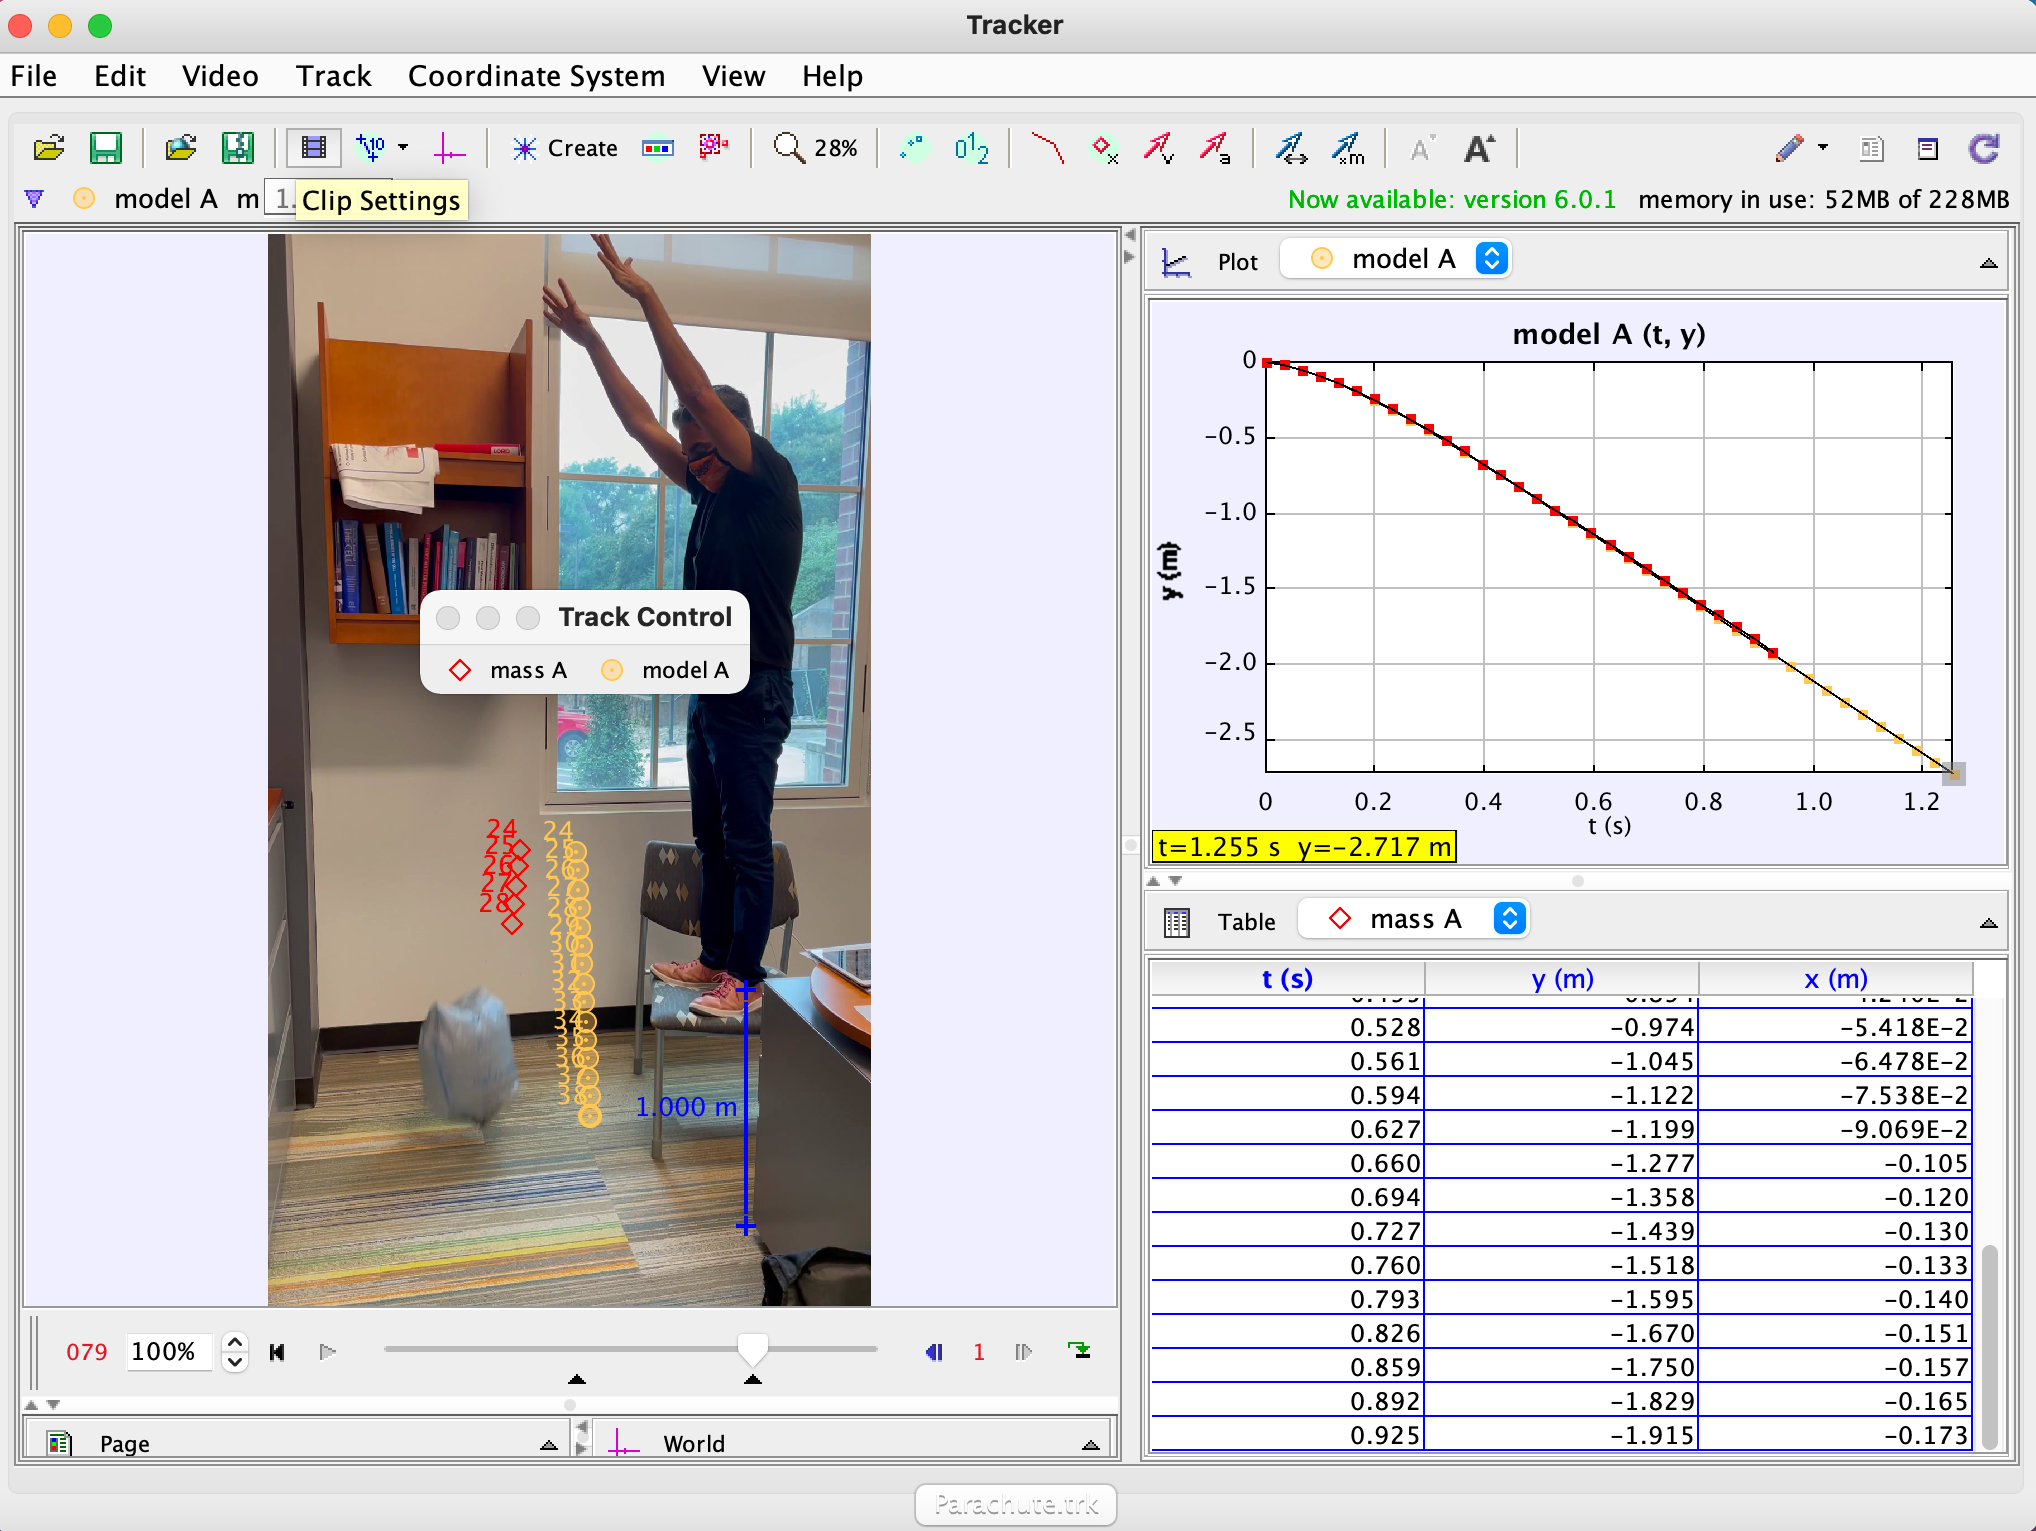

With these assumptions the equations of motion reduce to 

Newton's Equation: $m\;\frac{{\textrm{dV}}_y }{\textrm{dt}}=-m\;g+F_f ,$

Definition of velocity: $\frac{\textrm{dy}}{\textrm{dt}}=V_y$

Upon substitution for frictional forces, we get the two differential equations that determine the parachute dynamics:

 
$$m\;\frac{{\textrm{dV}}_y }{\textrm{dt}}=-m\;g+\alpha \;{\left(V_y \right)}^2 ,$$
 
$$V_y \left(t=0\right)=0$$



$$\frac{\textrm{dy}}{\textrm{dt}}=V_y ,\;\;y\left(t=0\right)=y_0$$
  

#### Our goal: **Use Matlab to solve the above Eqs, subject to the appropriate initial conditions.**

## `Solve the Eqs:`

To solve the Eqs we first need to use Euler's method (like the previous example) to discretize the derivative terms: 

$\frac{{\textrm{dV}}_y \left(t\right)}{\textrm{dt}}\approx \;\frac{V_y \left(t+\Delta \;t\right)-V_y \left(t\right)}{\Delta \;t}$,     $\frac{\textrm{dy}\left(t\right)}{\textrm{dt}}\approx \;\frac{y\left(t+\Delta \;t\right)-y\left(t\right)}{\Delta \;t}$

Upon substitution and some algebra, the equations simplify to:

### 
$$\begin{array}{l}
{\left(1\right)\;\;\;\;\;\;\;\;\;\;\;\;\;\;V}_y \left(t+\Delta \;t\right)=V_y \left(t\right)+\left(-g+\frac{\alpha \;}{m}{\left(V_y \left(t\right)\right)}^2 \right)\Delta \;t,\;\;\;V_y \left(0\right)=0,\\
\left(2\right)\;\;\;\;\;\;\;\;\;\;\;\;\;\;y\left(t+\Delta \;t\right)=y\left(t\right)+V_y \left(t\right)\Delta \;t,\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;y\left(0\right)=y_0 \ldotp \;
\end{array}$$
 

## `Task 1: `

Use the discretized forms of the equations for the velocity and position and the initial conditions to solve for position and velocity vs time before the parachute reaches the floor (use a "while" loop). 

- Use your initial value of position from Tracker to set $y_0$, which is basically the initial position of the parachute in your Table. 

- **Note: **You need to redefine your coordinate axis in Tracker, such that y=0 defines ground level. So, the origin should be at the bottom of your calibration stick. 

- As a starting point, try $\beta =\frac{\alpha \;}{m\;}=0\ldotp 50\;m^{-1}$.   This value is already included in the code. 

clc;clear;%Clean the workspace
close all; %Close all the existing figures 

%Initial Conditions 
Vy0=0.0;  % (m/s)Initial condition for velocity in y-direction 
beta=0.50;% 1/m: Value of beta=alpha/m, as stated in the text above.  
dt=0.01; %(s); delta t used in the simulations to approximate the derivatives
g=9.8; % (m/s^2)
%y0=

%Your code starts here:
%start by defining y0 based on the intial position of the parachute from
%Tracker.

## `Task 2: Compare against experiments`

- Use the same process as the falling ball activity to export the data (position, velocity, time) from Tracker to Matlab. Make sure that you delete the first row of this csv file and locate it in the same folder as this mlx file. Then set your Matlab workspace to this folder as well.  

- Not recommended (last resort): If you are having difficulty loading the data file ("data.txt" or "data.csv") into matlab , you can simply paste your data directly into an array say called "Data" in your code. 

- For both y and Vy, plot the measurements from Tracker and the simulation from Matlab on the same set of axes (you should have two plots, including one for y and one for Vy). Be sure to label the axes and legend for each plot.

- Use trial and error (different choices of $\beta \;$) to find the value for $\beta \;$that produces the best agreement between observations and predictions. 

%your code starts here

